# Antiderivatives

[⇦ Overview](matlab: OpenOverview)

The rates of change of variables turn up frequently when studying real-life interactions including velocity, acceleration, and current. In cases where we know the derivative and we want to determine the original function, we want to find the *antiderivative. *

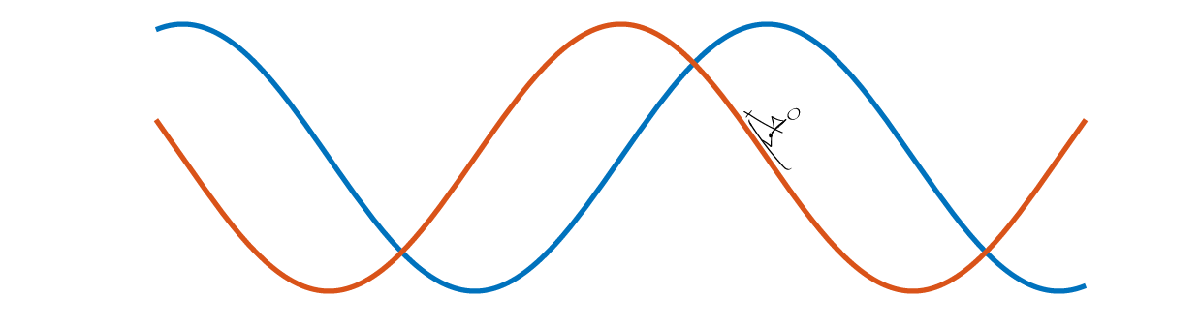

By using the knowledge of derivatives, it is possible to define an operation that will undo a derivative. 

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

## Families of Antiderivatives

$\displaystyle\int f(x) \; dx = F(x) +C,$                       for any constant $C$

f = @(x) sin(x);
 
xVals = -5:.02:5;
syms x
F(x) = int(f,x);
figure
pfC = drawFamily(xVals,F(xVals));

To select a particular element of the family, choose a value of $C$.

C = 0; 
ani = false;
if ~exist("pfC","var")
    xVals = -5:.02:5;
    syms x
    f(x) = sin(x); % Setting default values
    F(x) = int(f,x);
    figure
    pfC = drawFamily(xVals,F(xVals));
end
if ani
    % Identify maximum and minimum values range of plotted family members to
    % determine a reasonable window
    Fx = double(F(xVals)); 
    FxMin = min(Fx);
    FxMax = max(Fx);
    pfC.Parent.YLim = [FxMin FxMax] + [-10 10];

    % Animate the plot
    for C = [-10:.25:10 10:-.25:-10]
        pfC.YData = Fx + C;
        subtitle(pfC.Parent,"$C = $"+C,"Interpreter","latex");
        drawnow
    end
else
    pfC.YData = F(xVals)+C; 
    subtitle(pfC.Parent,"$C = $"+C,"Interpreter","latex");
end
drawnow

[⇦ Overview](matlab: OpenOverview)

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function pfC = drawFamily(xVals,FxVals)
    pf = plot(xVals,FxVals,"k","LineWidth",3);
    hold on
    pfC = copyobj(pf,pf.Parent);
    pfC.Color = [1 0 0];
    pfC.Parent.YLim = [min(double(FxVals))-8 max(double(FxVals))+8];
    Copts = [-10:.5:-.5 .5:.5:10];
    FVals = FxVals+Copts';
    plot(pf.Parent,xVals,FVals,"b","LineWidth",1);
    hold off
title("Plotting the family of antiderivatives $F(x)+C$","Interpreter","latex")
subtitle(pfC.Parent,"$C = $"+0,"Interpreter","latex");
legend(pf.Parent,["F(x)" "F(x)+C" "Family of F(x)"],"Location","bestoutside")
end

% Suppress warning message about unreachable code behind live controls
%#ok<*UNRCH>